# **RT-QIBC**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
m = matfile([dataDir filesep 'gemDbox_alldata.mat']);

dat = m.S(1,1);
dat = dat{1};
gate = m.gates_all(1,1);
gate = gate{1};
medEdU = m.medEdU_all(1,1);

**Plot CRL4norm levels DMSO**

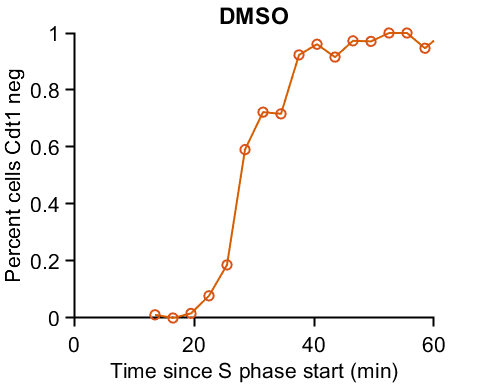

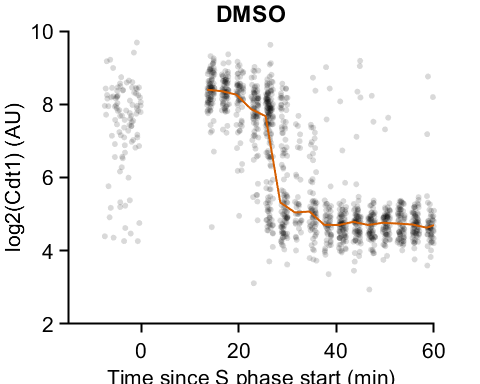

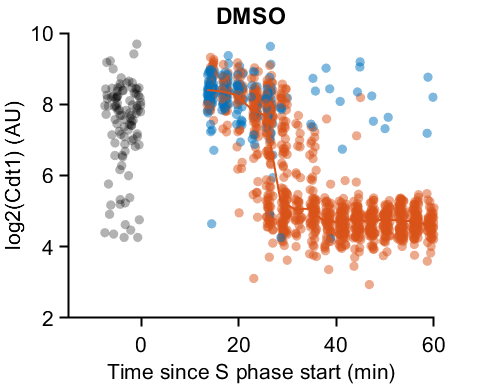

conds=[1];
poiAligned=3;
offset=-1;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);

gateVals = {{}};
rangeVals = {{}};

% range = linspace(0,4,10);
edges = (0:1/dat(1).framesPerHr:10);
midpoints = edges + (edges(2) -edges(1))/2;
midpoints = midpoints(1:end-1);

for i=1:length(conds)
    ind= gate_vals(dat(conds(i)), gateVals{i}, rangeVals{i});
    
    xdata = dat(conds(i)).POI_time(ind,poiAligned);
    ydata = [];
    ydata(:, 1) = log2(dat(conds(i)).YFP1(ind));
    ydata(:, 2) = log2(dat(conds(i)).YFP2(ind));
    ydata(:, 3) = log2(dat(conds(i)).FarRed1(ind)) ;
    
    
    threshs ={{log2(gate.YFP1_S(2)), -1}, {gate.YFP2_G1(2), 1}, {gate.FarRed1_G1(2), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',edges);    
    
    %%% Get G1 levels
    inds = dat(conds(i)).POI_time(:,1) <= 2 & dat(conds(i)).POI_time(:,1) > 1 &...
        isnan(dat(conds(i)).POI(:,3));
    g1Y = log2(dat(conds(i)).YFP1(ind));
    subsinds = randsample(length(g1Y),100);
    g1Y = g1Y(subsinds);
    jitterX = rand(size(g1Y))*.125 - 0.125;
    
        
     %%% Plot black and colored by Cdt1 levels
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
    hold on
    scatter(xdata*60,ydata(:,1),20,'k','filled','MarkerFaceAlpha',.15);
    plot(midpoints*60,binData(1).median,'LineWidth',1.5,'Color',[213 94 0]/255);
%     ylim([2 10]);
    xlim([-.25 1]*60);
    ylabel('log2(Cdt1) (AU)');xlabel('Time since S phase start (min)');
    title(dat(1).conditions{conds(i),1});
%     h=hline(log2([gate.YFP1_S gate.YFP1_G1(2)]),'k--');
    scatter(jitterX*60,g1Y,20,'k','filled','MarkerFaceAlpha',.15);
    pbaspect([1.25 1 1])
    print_pdf([pwd() '\Figs\C202_Cdt1_time.pdf'])
    
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
    hold on
    eduneg = ydata(:,3) < log2(gate.FarRed1_G1(2));
    edupos = ydata(:,3) >= log2(gate.FarRed1_G1(2));
    colors = zeros(length(eduneg),3);
    colors(eduneg,:) = repmat([0 0.4470 0.7410],sum(eduneg),1);
    colors(edupos,:) = repmat([0.8500 0.3250 0.0980],sum(edupos),1);
    scatter(xdata*60,ydata(:,1),50,colors,...
        'filled','MarkerFaceAlpha',.5);
    plot(midpoints*60,binData(1).median,'LineWidth',1.5);
    scatter(jitterX*60,g1Y,50,'k','filled','MarkerFaceAlpha',.3);     
    %ylim([4 10]);
    xlim([-.25 1]*60);
    ylabel('log2(Cdt1) (AU)');xlabel('Time since S phase start (min)');
    title(dat(1).conditions{conds(i),1});
%     h=hline(log2([gate.YFP1_S gate.YFP1_G1(2)]),'k--');
    
    figure(f1)
    hold on
    plot(midpoints*60,binData(1).perc,'LineWidth',1.5,'Color',[213 94 0]/255);
    scatter(midpoints*60,binData(1).perc,50,'LineWidth',1.5);
    ylabel('Percent cells Cdt1 neg');xlabel('Time since S phase start (min)');
    title(dat(1).conditions{conds(i),1});
    xlim([0 60])
    ylim([0 1])
    %cells = length(xdata)
    
end

**stat test EdU comparison DMSO/DOX zeroed**

Gate for early mitosis, first .3 hrs, high/low geminin

rng(1)
xval = 'YFP1';
yval = 'YFP2';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = dat(condition).(yval) - gate.YFP2_G1(1);

inds = dat(condition).POI_time(:,1) <= 1.5 & dat(condition).POI_time(:,1) >= 1 & ...
    dat(condition).FarRed1 < gate.FarRed1_G1(2) & dat(condition).YFP1 > 2^7  & dat(condition).dna < 2^21;
ydata = ydata(inds);

inds = randsample(length(ydata),700);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  1;
ydata = dat(condition).(yval)- gate.YFP2_G1(1);

inds = dat(condition).POI_time(:,3) <= .5 & dat(condition).FarRed1 < 2^9 & dat(condition).dna < 2^21 ...
    & dat(condition).YFP1 > 2*gate.YFP1_S(2);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21 & dat(condition).allFarRed1 > 2^8.5 ...
    & dat(condition).allFarRed1 < 2^12 & dat(condition).allYFP1 < gate.YFP1_G1(1);
ydata = dat(condition).allYFP2(ind) - gate.YFP2_G1(1);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
ally = ally/median(ally(group == 3));
median(ally(group==2))

ans = 0.0980

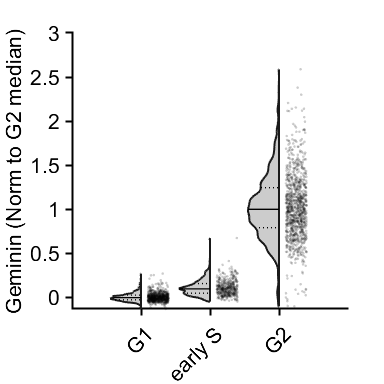

%test = cellfun(@(x) x/median(test{3}),test,'UniformOutput',false);

% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% notBoxPlot((ally),group)

% jit = 0.5*(rand(size(group))-0.5);
% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% scatter(group+jit, (ally), 10,'k','filled','MarkerFaceAlpha',.2);
% xlim([0 max(group)+1])
% 
% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% violinPlot((ally),'groups',group, 'showMM',5,'histOpt',1,'divFactor',1.5)

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.2);
ylabel('Geminin (Norm to G2 median)')
% ylim([0 2.25])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\C202_gmnn_compare_scatter_zero.pdf'])